clc;clear
x=load('ex4x.dat');
y=load('ex4y.dat');
% plot(x,y,'o')
[m,n]=size(x)

m = 80

n = 2

x=[ones(m,1),x]

x =     1.0000   55.5000   69.5000
    1.0000   41.0000   81.5000
    1.0000   53.5000   86.0000
    1.0000   46.0000   84.0000
    1.0000   41.0000   73.5000
    1.0000   51.5000   69.0000
    1.0000   51.0000   62.5000
    1.0000   42.0000   75.0000
    1.0000   53.5000   83.0000
    1.0000   57.5000   71.0000


pos=find(y==1)

pos =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


neg=find(y==0)

neg =     41
    42
    43
    44
    45
    46
    47
    48
    49
    50


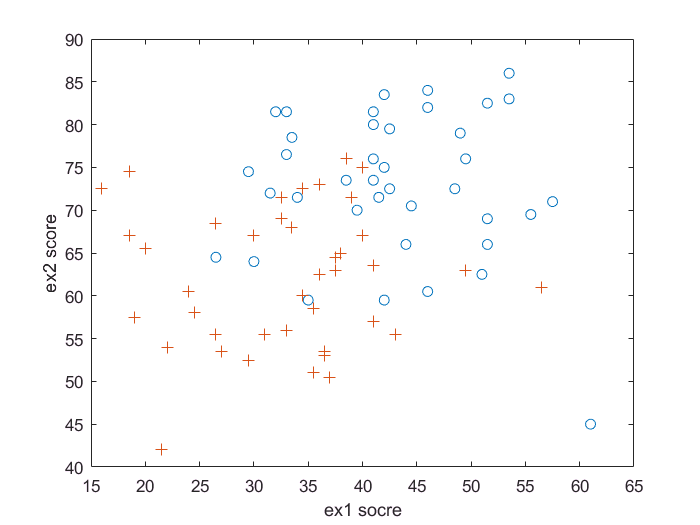

figure
plot(x(pos,2),x(pos,3),'o')
hold on 
plot(x(neg,2),x(neg,3),'+')
hold on 
xlabel('ex1 socre')
ylabel('ex2 score')

theta=zeros(size(x,2),1)

theta =      0
     0
     0


sig=inline('1./(1+exp(-z))')


sig =

     内联函数:
     sig(z) = 1./(1+exp(-z))



iter_max=7

iter_max = 7

j=zeros(iter_max,1)

j =      0
     0
     0
     0
     0
     0
     0


for i =1:iter_max
    z=x*theta
    h=sig(z)
    grad=(1/m).*x'*(h-y)
    H=(1/m).*x'.*diag(h)*diag(1-h)*x
    
    J(i)=(1/m)*sum(-y.*log(h)-(1-y).*log(1-h))
    theta=theta-H/grad
    
%     x=A/B x*B=A x=A*inv(B)
%     x=A\B A*x=B x=inv(A)*B
end

z =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


grad =     0.0000
   -2.5563
   -2.6281


错误使用  .* 
矩阵维度必须一致。
